%Symbolic Assignment, Mechanic of Machinery

clear all;

%Preliminary Coordinates
format short

A = [0,-0.6,.05];
B = [0,0,1.5];
C_rel_B = [0,.35,-.085];
AB = sqrt(sum((A-B).^2));
BC = sqrt(sum(C_rel_B.^2));

gamma = atan((A(2)-B(2))/(B(3)-A(3)));
beta = atan(-C_rel_B(3)/C_rel_B(2));

n = 1000;
theta_target = deg2rad(linspace(-60,0,n));

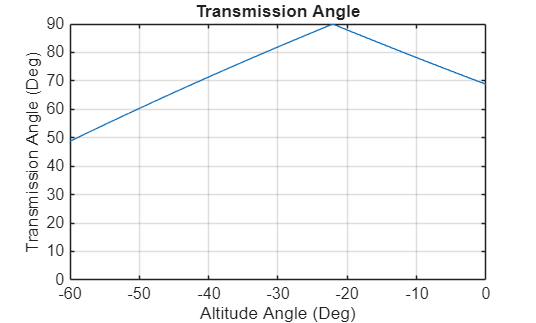

%Solving for L_AC
syms theta alpha AC
eq1 = AC^2 == AB^2+BC^2-2*AB*BC*cos(alpha);
eq2 = theta + pi/2 == alpha+beta+gamma;
sol = solve([eq1,eq2],[alpha,AC]);
AC_sol = sol.AC(2);
alpha_sol = sol.alpha(2);

%Minimal Transmission Angle
sine_BCA = sin(alpha_sol)*AB/AC_sol;
BCA = asin(sine_BCA );
BCA_all = rad2deg(double(subs(BCA,theta_target)));
plot(linspace(-60,0,n),BCA_all)
grid on
ylim([0,90])
title("Transmission Angle")
xlabel('Altitude Angle (Deg)')
ylabel('Transmission Angle (Deg)')

BCA_min = min(BCA_all)

BCA_min = 48.7688

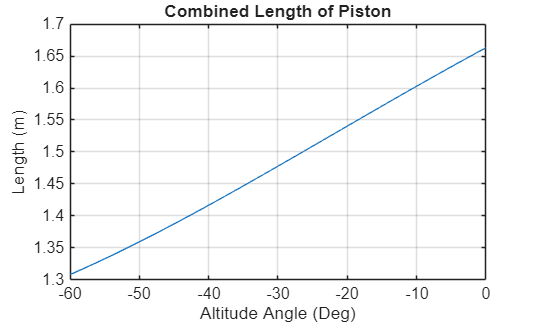


%Length AC
AC_all = double(subs(AC_sol,theta_target));
plot(linspace(-60,0,n),AC_all)
grid on
title("Combined Length of Piston")
xlabel('Altitude Angle (Deg)')
ylabel('Length (m)')

AC_min = min(AC_all)

AC_min = 1.3083

AC_max = max(AC_all)

AC_max = 1.6630

del_AC = AC_max-AC_min

del_AC = 0.3548


%Determine Position C
C = B+BC*[0,cos(theta-beta),sin(theta-beta)];

%Panel Position Analysis
panel_top = B+1.5/2*[0,cos(theta),sin(theta)];
panel_bottom = B-1.5/2*[0,cos(theta),sin(theta)];
panel_top_drawx = double(subs(panel_top(1),theta_target));
panel_top_drawy = double(subs(panel_top(2),theta_target));
panel_top_drawz = double(subs(panel_top(3),theta_target));
panel_bottom_drawx = double(subs(panel_bottom(1),theta_target));
panel_bottom_drawy = double(subs(panel_bottom(2),theta_target));
panel_bottom_drawz = double(subs(panel_bottom(3),theta_target));


panel_con = B+C_rel_B(2)*[0,cos(theta),sin(theta)];
panel_con_drawx = double(subs(panel_con(1),theta_target));
panel_con_drawy = double(subs(panel_con(2),theta_target));
panel_con_drawz = double(subs(panel_con(3),theta_target));


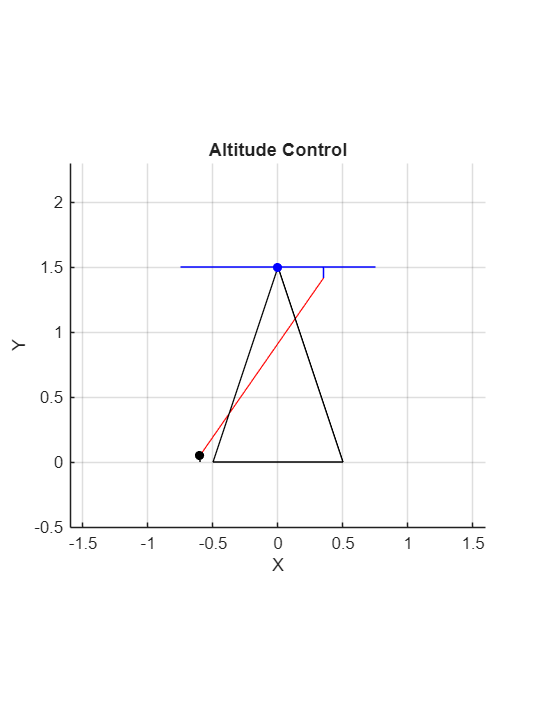

%Visualise

%2D
figure('Position', [100, 100, 1200, 1600])
hold on
axis equal
grid on
xlabel('X')
ylabel('Y')
title('Altitude Control')
xlim([-1.6, 1.6])
ylim([-0.5, 2.3])

h_AB = animatedline('color','black','LineStyle',"--");
h_BC = animatedline('color','green','LineStyle',"--");
h_CA = animatedline('color','red');
h_base = animatedline('color','black');
h_base_con = animatedline('color','black');

Cx_draw = double(subs(C(1),theta_target));
Cy_draw = double(subs(C(2),theta_target));
Cz_draw = double(subs(C(3),theta_target));

%Draw panel
h_panel = animatedline('Color','blue');
h_panel_con = animatedline('Color','blue');

p_base_con = plot(A(2),A(3),'ko',markerfacecolor = 'black',markersize = 5);
p_panel_piv = plot(B(2),B(3),'bo',markerfacecolor = 'blue',markersize = 5);

%Simulate
%addpoints(h_AB,[A(2),B(2)],[A(3),B(3)]);
addpoints(h_base,[-.5,0,.5,-.5],[0,B(3),0,0]);
addpoints(h_base_con,[A(2),A(2)],[0,A(3)]);
skip = floor(n/40);


for i = 1:skip:n
    %clearpoints(h_BC);
    clearpoints(h_CA);
    clearpoints(h_panel);
    clearpoints(h_panel_con);
    
    
    %addpoints(h_BC,[B(2),Cy_draw(i)],[B(3),Cz_draw(i)]);
    addpoints(h_CA,[Cy_draw(i),A(2)],[Cz_draw(i),A(3)]);
    addpoints(h_panel,[panel_top_drawy(i),panel_bottom_drawy(i)],[panel_top_drawz(i),panel_bottom_drawz(i)]);
    addpoints(h_panel_con,[Cy_draw(i),panel_con_drawy(i)],[Cz_draw(i),panel_con_drawz(i)]);
    drawnow 

    pause(.1)
end

%clearpoints(h_BC);
clearpoints(h_CA);
clearpoints(h_panel);
clearpoints(h_panel_con);


%addpoints(h_BC,[B(2),Cy_draw(i)],[B(3),Cz_draw(i)]);
addpoints(h_CA,[Cy_draw(n),A(2)],[Cz_draw(n),A(3)]);
addpoints(h_panel,[panel_top_drawy(n),panel_bottom_drawy(n)],[panel_top_drawz(n),panel_bottom_drawz(n)]);
addpoints(h_panel_con,[Cy_draw(n),panel_con_drawy(n)],[Cz_draw(n),panel_con_drawz(n)]);

drawnow 

pause(.1)

